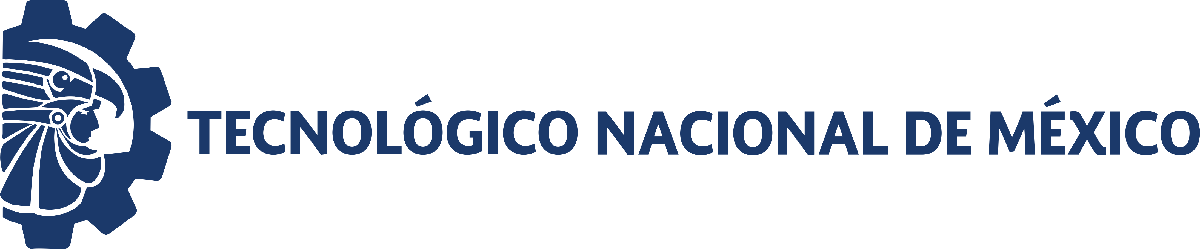                                 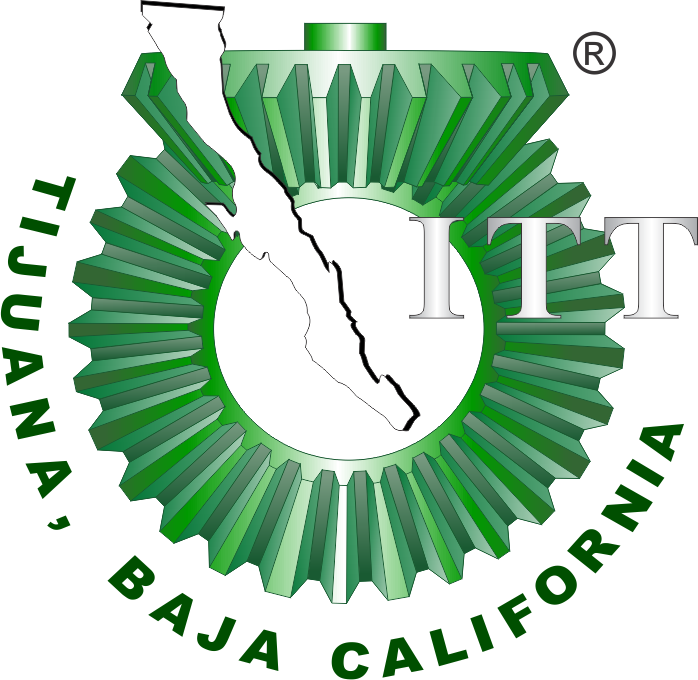

# Práctica cuatro: Modelado y control del sistema endócrino

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

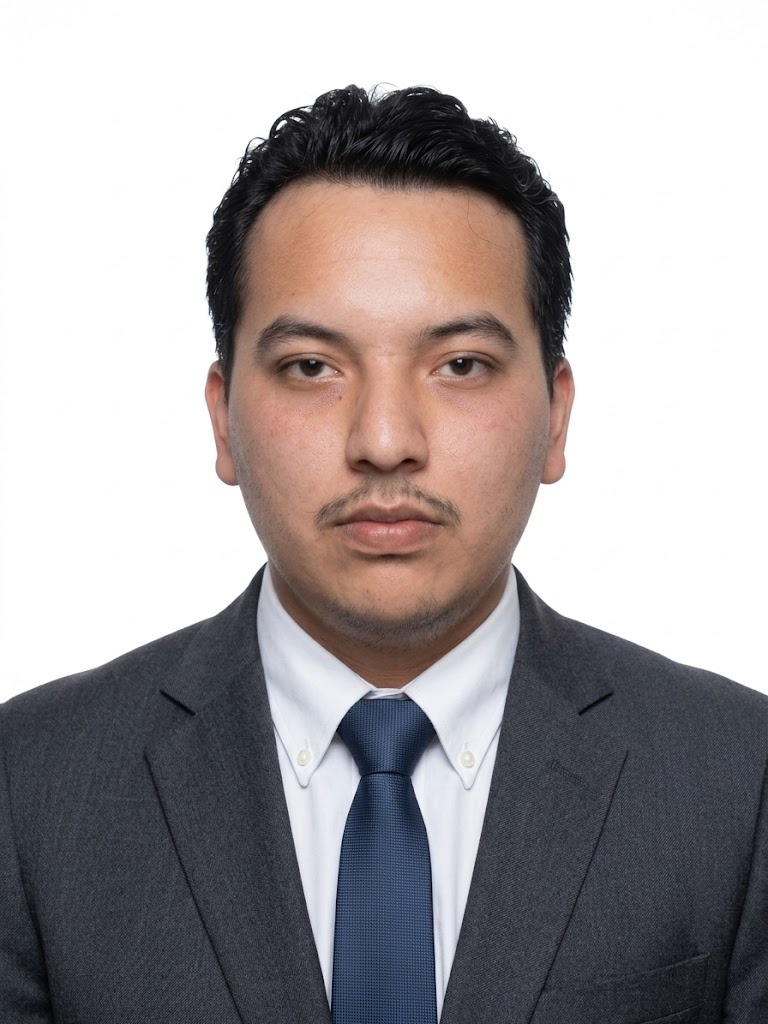

Nombre del alumno: **Garcia Grijalva Armando**

Número de control: **23212195**

Correo institucional: **L23212195@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
file = 'SistemaP4'

file = 'SistemaP4'

open_system(file)
tend = '10';
parameters.StopTime = tend;
parameters.Solver = 'ode15s';
parameters.MaxStep = '1E-3';

## Respuesta al escalón

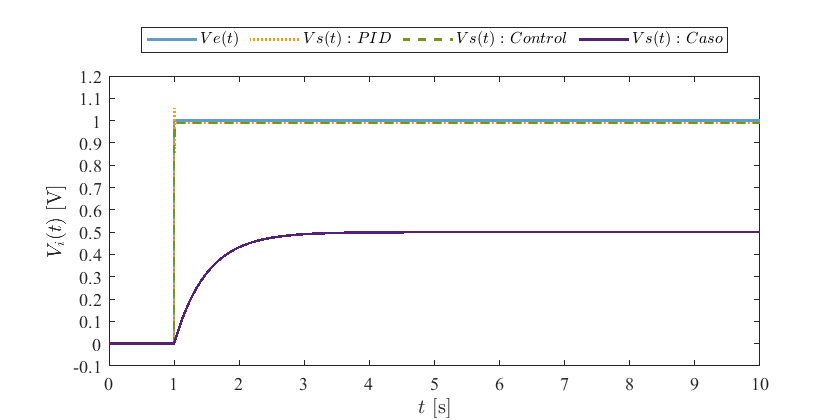

x = sim(file,parameters);
plotSignals(x.t,x.Ve,x.PID,x.control,x.caso)

## Función: Respuestas de la simulación

function plotSignals(t,Ve,PID,control,caso)
    set(figure(),'color','w')
    set(gcf,'units','inches','position',[1,1,7,3.5])
    set(gca,'fontname','times new roman','fontsize',11)
    hold on; grid off; box on;
    clr1 = [97, 157, 198]/255;
    clr2 = [255, 154, 0]/255;
    clr3 = [113, 149, 30]/255;
    clr4 = [84, 33, 119]/255;
    order = [clr1;clr2;clr3;clr4]; colororder(order)
    
    plot(t,Ve,'-',t,PID,':',t,control,'--',t,caso,'-','LineWidth',1.5,'MarkerSize',5,'MarkerIndices',...
        1:1e3:length(t));
    
    L = legend('$Ve(t)$','$Vs(t): PID$','$Vs(t): Control$','$Vs(t): Caso$');
    set(L,'interpreter','latex','location','northoutside','orientation','horizontal')
    
    xlabel('$t$ [s]','interpreter','latex')
    ylabel('$V_i(t)$ [V]','interpreter','latex')
    
    xlim([0 10]); xticks(0:1:10)
    ylim([-0.1 1.2]); yticks(-0.1:0.1:1.2)
    
    exportgraphics(gcf,['SeñalEndocrino_matlab.pdf'],'contenttype','vector')
end